## 6.1 Applying the 2-D DFT on an image

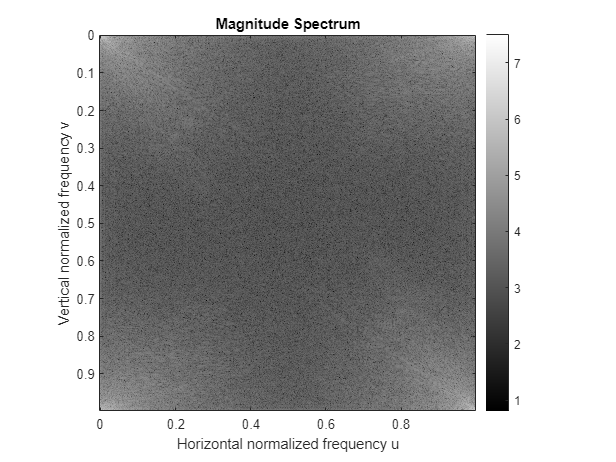

% Compute 2D DFT of an image
f = double(imread('Lena.bmp')); % read an image
[H, W ] = size(f); % image size
F = fft2(f); % compute 2-D DFT
F_mag = abs(F); % compute the magnitude spectrum
% Visualize the magnitude spectrum
u = 0:1/W:1-1/W; % Horizontal normalized frequencies
v = 0:1/H:1-1/H; % Vertical normalized frequencies
imagesc(v, u, log10(1 + F_mag)); % Magnitude spectrum versus normalized frequencies
colorbar, colormap gray, axis image
title('Magnitude Spectrum');
xlabel('Horizontal normalized frequency u');
ylabel('Vertical normalized frequency v');